１：全モデルでの平均音速値をプロットする．ここで構造の影響が大きく出ているデータを目視で特定する．

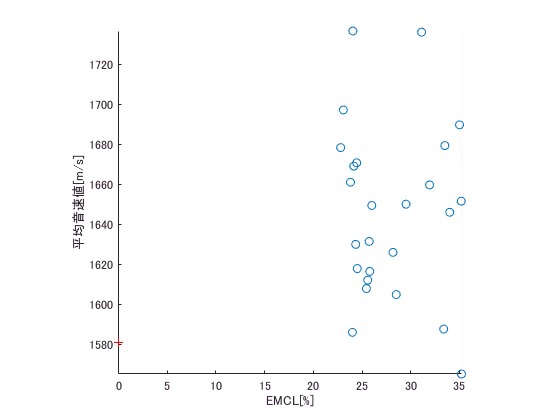

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_12_analyzeRealisticModel\2018_08_12_failure')
load('2018_08_05_aveSOS&steSOS_1-25')
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\medium\2018_08_10_realisticScatter')
load('rate_EMCLs')
[~, num_pattern] = size(aveSOS);
v_muscle = 1580;
v_fat = 1450;
figure;
hold on
scatter(rate_EMCLs(1,:), aveSOS(1,:));
% plot(,v_muscle*(1-x1/100)+v_fat*x1/100,'--');
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_08_08_no_object')
load('2018_08_08_aveSOS&steSOS')
scatter(0,aveSOS,'r+');
xlabel('EMCL[%]');
ylabel('平均音速値[m/s]')
axis square
axis tight
hold off

結果がぐちゃぐちゃになってしまった．何かがおかしい．

２：１はtof-map作成の時点で失敗している．

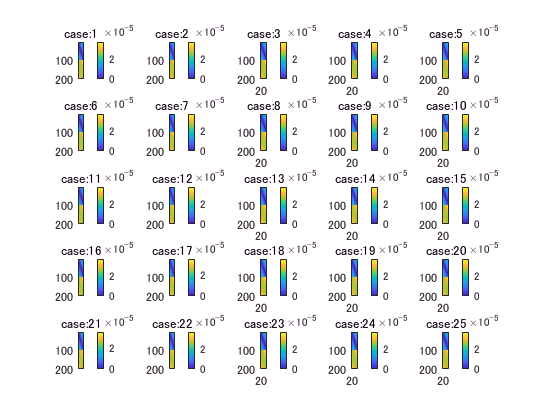

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_12_analyzeRealisticModel\2018_08_12_failure')
load('2018_08_05_aveSOS&steSOS_1-25')
figure;
for i = 1:25
    subplot(5,5,i);
    imagesc(tof_cell(:,:,i));
    colorbar
    myfilename = sprintf('case:%d',i);
    title(myfilename);
end

３：tof-pickerを設定し直す．

%まずはtofデータ一個を取り出して考える．
% cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_08_08_no_object')
% load('NoObject')
% tof_data_r0 = tof_data;
% [tof_x, tof_y] = size(tof_data_r0);
addpath(genpath('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\codes'))
%RFデータを読みこむ
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_08_05_no_object\NoObject')
load('rfdata.mat')
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_08_05_no_object\NoObject');
load('kgrid')
rfdata_no_object = rfdata;

tof_map = threshold_picker(rfdata_no_object,kgrid);
v_cal_no_object = 40e-03/tof_map(150,50)

v_cal_no_object = 1.5804e+03

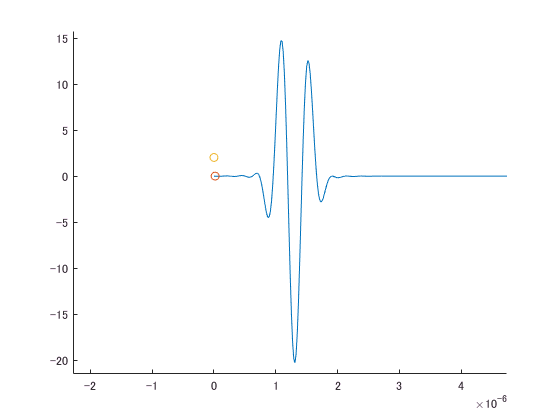

figure;
hold on
plot(kgrid.t_array(1,:),rfdata_no_object(:,50,50));
xlim([-0.00000228 0.00000474])
ylim([-21.52 15.78])
scatter(tof_map(50,50),0);
scatter(0,threshold_map(50,50));

４：rfdata（肉断面），特にtof-map生成に失敗した原因となった箇所のｒｆデータを見る．

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_08_12_realisticScatter')
cd('case1')
load('rfdata.mat')
load('kgrid.mat')

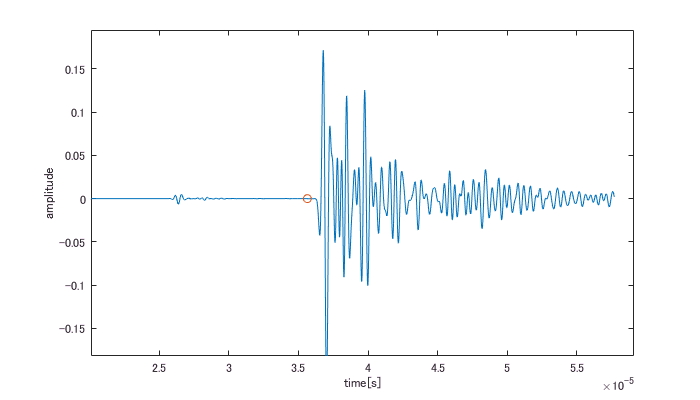

figure;
plot(kgrid.t_array(1,:),rfdata(:,200,5))
hold on
tof_map = threshold_picker(rfdata,kgrid);
scatter(tof_map(200,5),0);
xlabel('time[s]')
ylabel('amplitude')
xlim([0.0000201 0.0000591])
ylim([-0.182 0.195])
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_12_analyzeRealisticModel\rfdata_tr_5_re_200','png',[700,400]);

初期微動のようなものが最初に来ている．これを誤って拾ってしまったのだろう．

５：再度tof-mapを表示してみる．（k-wave\script参照）

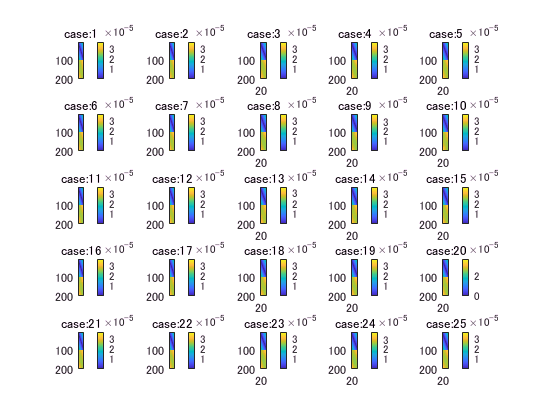

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_12_analyzeRealisticModel')
load('2018_08_12_aveSOS&steSOS_1-25')
figure;
for i = 1:25
    subplot(5,5,i);
    imagesc(tof_cell(:,:,i));
    colorbar
    myfilename = sprintf('case:%d',i);
    title(myfilename);
end

どうやらokみたいだ．

６：全モデルでの平均音速値をプロットする．再度．

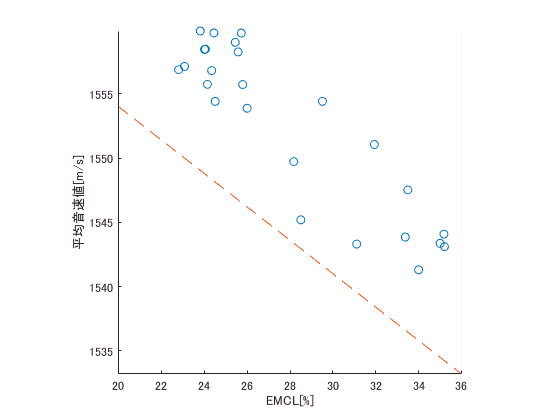

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_12_analyzeRealisticModel')
load('2018_08_12_aveSOS&steSOS_1-25')
load('rate_EMCLs')
[~, num_pattern] = size(aveSOS);
v_muscle = 1580;
v_fat = 1450;
x1 = 20:36;
figure;
hold on
scatter(rate_EMCLs(1,:), aveSOS(1,:));
plot(x1,v_muscle*(1-x1/100)+v_fat*x1/100,'--');
% cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_08_08_no_object')
% load('2018_08_08_aveSOS&steSOS')
% scatter(0,aveSOS,'r+');
xlabel('EMCL[%]');
ylabel('平均音速値[m/s]')
axis square
axis tight
hold off

かなり誤差が大きい．これでは正確に判定することは難しいだろう．

７：対向する素子ペアの距離（一定）と所要時間を用いた平均距離を用いて比較してみる．

addpath(genpath('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\codes'))
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\param')
load('param_2board.mat')
kgrid= makeGrid(param.grid.Nx, param.grid.dx, param.grid.Ny, param.grid.dy);

         Update codes to use the syntax kgrid = kWaveGrid(...).


cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_12_analyzeRealisticModel');
myfilename = sprintf('2018_08_12_aveSOS&steSOS_1-25.mat');
load(myfilename);
% tof_cell  = zeros(200,100,25);%{Receiver, Transmitter, ERate, Num, }
aveSOS2 = zeros(1,25);%{ERate, Num}
steSOS2_0 = zeros(100,25);
steSOS2 = zeros(1,25);
leng = zeros(1,100);
t_size = 40.e-3;
t_num = 200;%トランスデューサ数
t_pos = zeros(2, t_num);%センサ位置
t_pos(1,1:t_num/2) = -t_size/2:t_size/(t_num/2-1):t_size/2 ;%素子水平方向距離[m]
t_pos(2,1:t_num/2) = t_size/2;
t_pos(1,t_num/2+1:t_num) = t_pos(1,1:t_num/2);
t_pos(2,t_num/2+1:t_num) = -t_size/2;

for i = 1:25
    [~,ind] = min(tof_cell(101:end,:,i));
end
for k = 1: t_num/2
    leng(1,k) = norm(t_pos(:,k)-t_pos(:,100+k));
end
for ii = 1:25
    for jj = 1:t_num/2
        aveSOS2(1,ii) = aveSOS2(1,ii) + leng(1,jj)/tof_cell(jj+100,jj,ii);
        steSOS2_0(jj,ii) = leng(1,jj)/tof_cell(jj+100,jj,ii);
    end
    aveSOS2(1,ii) = aveSOS2(1,ii)/(t_num/2);
    steSOS2(1,ii) = std(steSOS2_0(:,ii))/sqrt(t_num/2);
end

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_12_analyzeRealisticModel');
myfilename = sprintf('2018_08_12_aveSOS&steSOS_1-25');
save(myfilename,'aveSOS','steSOS','aveSOS2','steSOS2','tof_cell');

８：７で定義した平均音速も含めて全モデルでの平均音速値をプロットする．再度．

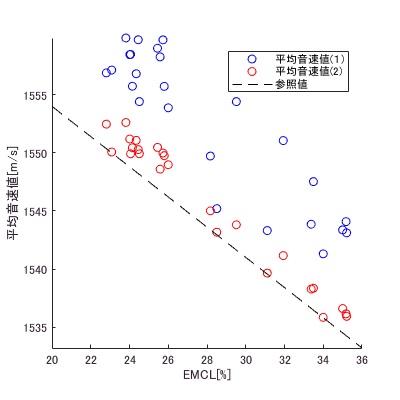

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_12_analyzeRealisticModel')
load('2018_08_12_aveSOS&steSOS_1-25')
load('rate_EMCLs')
[~, num_pattern] = size(aveSOS);
v_muscle = 1580;
v_fat = 1450;
x1 = 20:36;
figure;
hold on
scatter(rate_EMCLs(1,:), aveSOS(1,:),'b');
scatter(rate_EMCLs(1,:), aveSOS2(1,:),'r');
plot(x1,v_muscle*(1-x1/100)+v_fat*x1/100,'k--');
% cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_08_08_no_object')
% load('2018_08_08_aveSOS&steSOS')
% scatter(0,aveSOS,'r+');
xlabel('EMCL[%]');
ylabel('平均音速値[m/s]')
legend('平均音速値(１)','平均音速値(2)','参照値')
axis square
axis tight
hold off
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_12_analyzeRealisticModel\EMCL-aveSOS','png',[400,400]);

９：最速経路をとる素子ペアの関係

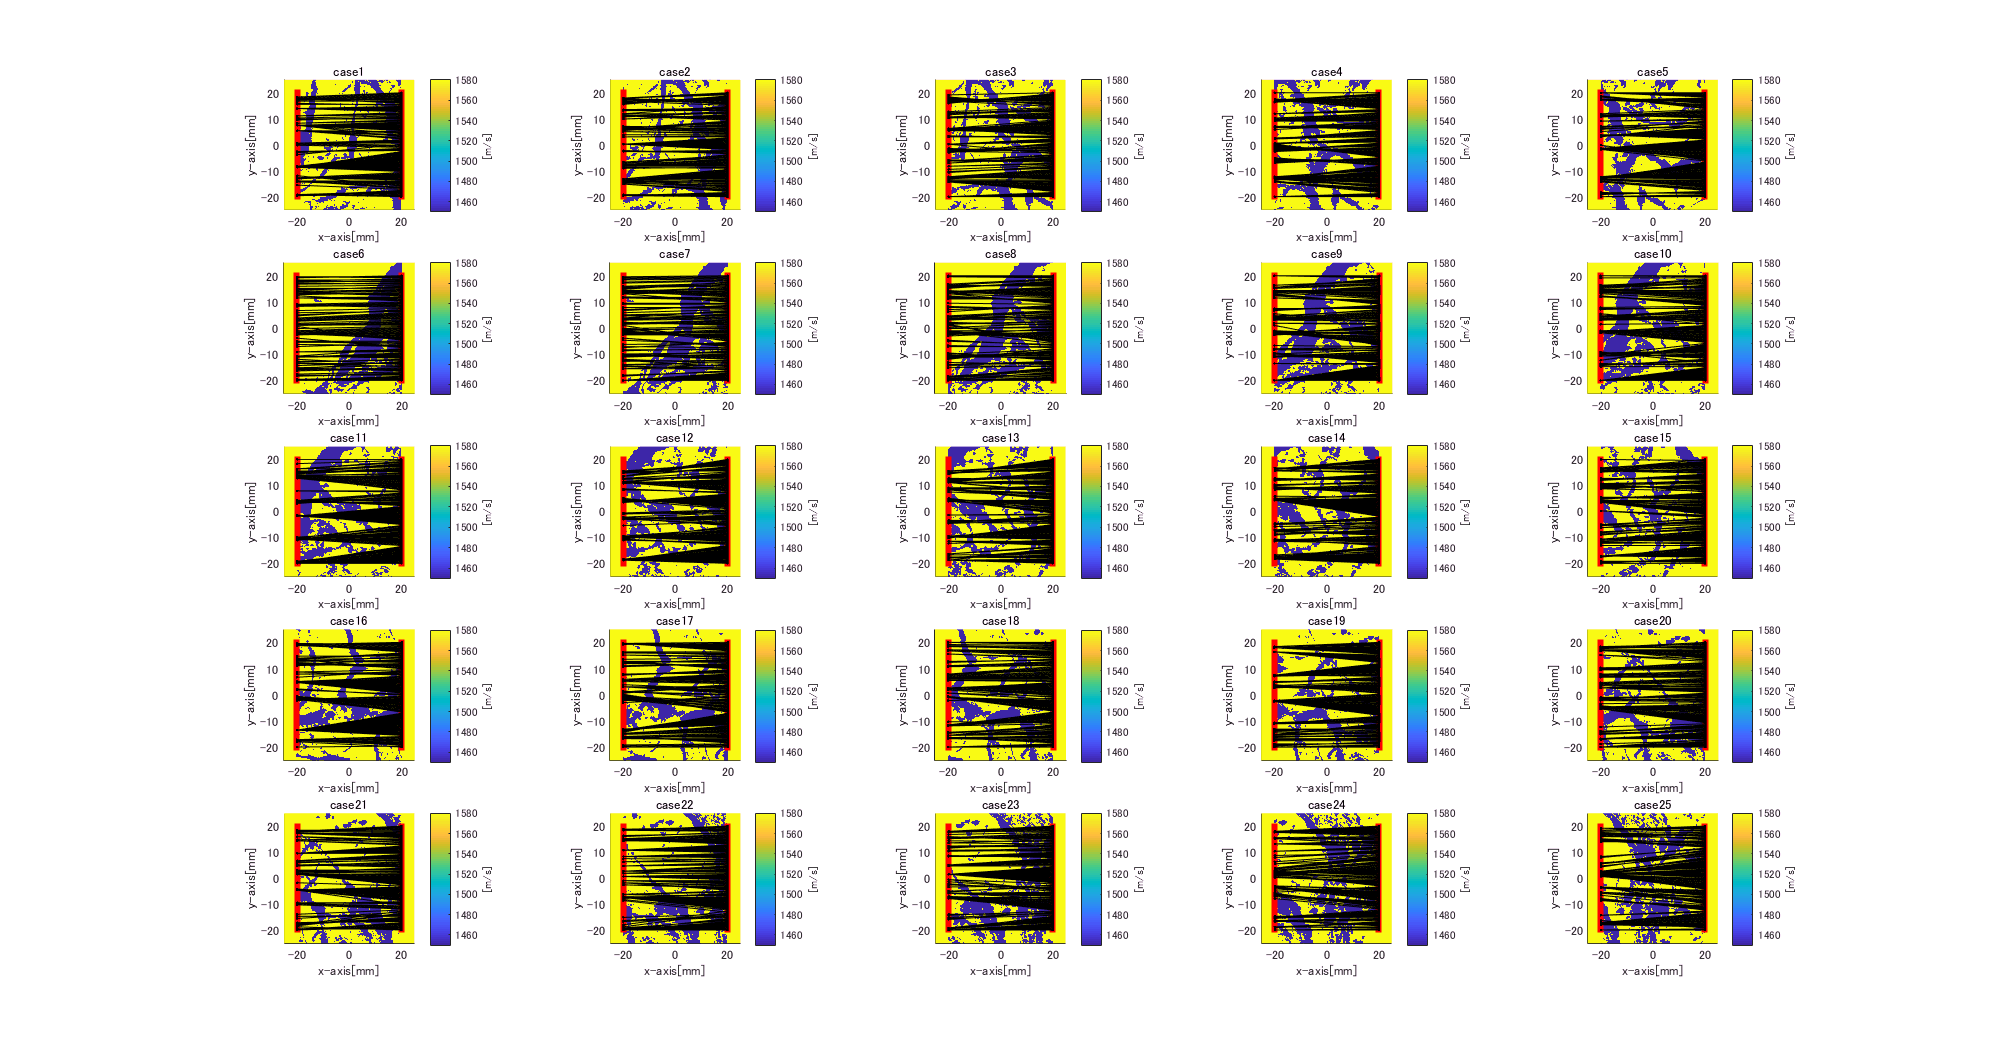

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\medium\2018_08_10_realisticScatter')
t_size = 40.e-3;
t_num = 200;%トランスデューサ数
t_pos = zeros(2, t_num);%センサ位置
t_pos(1,1:t_num/2) = -t_size/2:t_size/(t_num/2-1):t_size/2 ;%素子水平方向距離[m]
t_pos(2,1:t_num/2) = t_size/2;
t_pos(1,t_num/2+1:t_num) = t_pos(1,1:t_num/2);
t_pos(2,t_num/2+1:t_num) = -t_size/2;
figure;
for i = 1:25
    myfilename = sprintf('case%d',i);
    load(myfilename)
    subplot(5,5,i);
    hold on;
    imagesc(kgrid.x_vec*1000,kgrid.y_vec*1000,medium.sound_speed);
    axis equal
    axis tight
    scatter(t_pos(2,:)*1000,t_pos(1,:)*1000,'rs','filled');
    [~,ind] = min(tof_cell(101:end,:,i));
    ind = ind+100;
    for j = 1:length(ind)
        plot([t_pos(2,j)*1000;t_pos(2,ind(j))*1000],[t_pos(1,j)*1000;t_pos(1,ind(j))*1000],'.-k','LineWidth',0.01);
    end
    xlabel('x-axis[mm]')
    ylabel('y-axis[mm]')
    title(myfilename);
    colorbar;
    caxis([1450 1580]);
    c = colorbar;
    c.Label.String = '[m/s]';
    hold off;
end
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_12_analyzeRealisticModel\fastest_path_plot','png',[2000,2000]);

１０：l/tプロットを見て分散がどれだけあるのかを確認する．

１０－１：送信素子を固定して，全受信素子についてl/tプロットを行った．

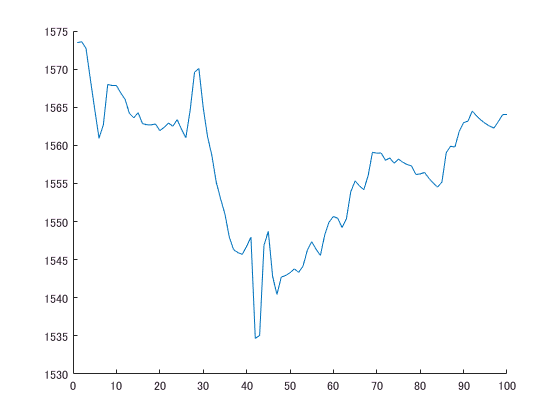

%まずはtofデータ一個を取り出して考える．
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_12_analyzeRealisticModel')
load('case1')
tof_data_1 = tof_data;
[tof_x, tof_y] = size(tof_data_1);
%leng変数を使う．
leng = zeros(tof_x,tof_y);
t_size = 40.e-3;
t_num = 200;%トランスデューサ数
t_pos = zeros(2, t_num);%センサ位置
t_pos(1,1:t_num/2) = -t_size/2:t_size/(t_num/2-1):t_size/2 ;%素子水平方向距離[m]
t_pos(2,1:t_num/2) = t_size/2;
t_pos(1,t_num/2+1:t_num) = t_pos(1,1:t_num/2);
t_pos(2,t_num/2+1:t_num) = -t_size/2;
for i = 1:t_num
    for j = 1:t_num/2
        leng(i,j) = sqrt((t_pos(1,i)-t_pos(1,j))^2+(t_pos(2,i)-t_pos(2,j))^2);
    end
end
v_1 = leng./tof_data_1;
%これでtofと素子間距離が対応付けられた．プロットする．
figure;
hold on
j = t_num/5;
plot(1:t_num/2,v_1(100+1:100+t_num/2,j));
hold off

１０－２：全素子ペアに注目してl/tプロットを行う．

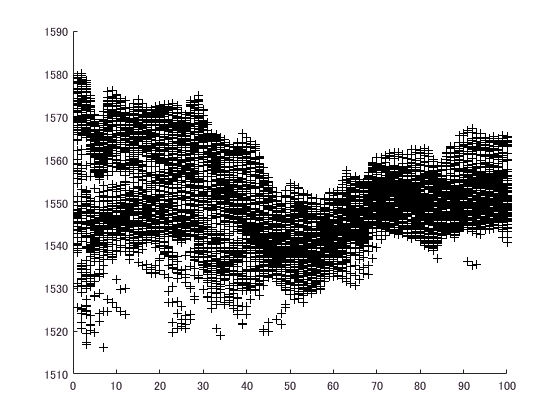

%まずはtofデータ一個を取り出して考える．
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_12_analyzeRealisticModel')
load('case1')
tof_data_1 = tof_data;
[tof_x, tof_y] = size(tof_data_1);
%leng変数を使う．
leng = zeros(tof_x,tof_y);
t_size = 40.e-3;
t_num = 200;%トランスデューサ数
t_pos = zeros(2, t_num);%センサ位置
t_pos(1,1:t_num/2) = -t_size/2:t_size/(t_num/2-1):t_size/2 ;%素子水平方向距離[m]
t_pos(2,1:t_num/2) = t_size/2;
t_pos(1,t_num/2+1:t_num) = t_pos(1,1:t_num/2);
t_pos(2,t_num/2+1:t_num) = -t_size/2;
for i = 1:t_num
    for j = 1:t_num/2
        leng(i,j) = sqrt((t_pos(1,i)-t_pos(1,j))^2+(t_pos(2,i)-t_pos(2,j))^2);
    end
end
v_1 = leng./tof_data_1;
%これでtofと素子間距離が対応付けられた．プロットする．
figure;
hold on
for ii = 1:t_num/2
    scatter(1:t_num/2,v_1(100+1:t_num,ii),'k+');
end
% for ii = 6:t_num/2-5
% scatter(ii-5:ii+5,v_1(ii-5+100:ii+5+100,ii),'ro');
% end
hold off

１０－３：各送信素子において全受信素子間での平均速度を上の図にプロットしなおす．

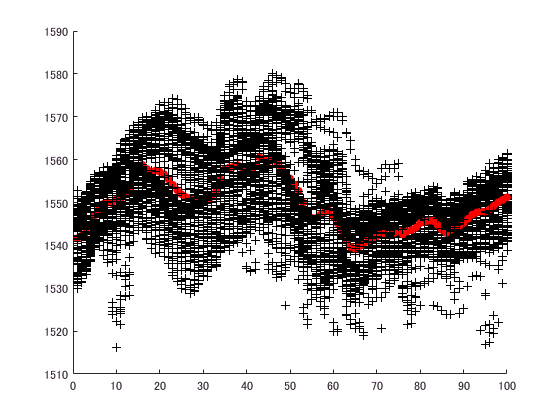

%まずはtofデータ一個を取り出して考える．
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_12_analyzeRealisticModel')
load('case1')
tof_data_1 = tof_data;
[tof_x, tof_y] = size(tof_data_1);
%leng変数を使う．
leng = zeros(tof_x,tof_y);
t_size = 40.e-3;
t_num = 200;%トランスデューサ数
t_pos = zeros(2, t_num);%センサ位置
t_pos(1,1:t_num/2) = -t_size/2:t_size/(t_num/2-1):t_size/2 ;%素子水平方向距離[m]
t_pos(2,1:t_num/2) = t_size/2;
t_pos(1,t_num/2+1:t_num) = t_pos(1,1:t_num/2);
t_pos(2,t_num/2+1:t_num) = -t_size/2;
for i = 1:t_num
    for j = 1:t_num/2
        leng(i,j) = sqrt((t_pos(1,i)-t_pos(1,j))^2+(t_pos(2,i)-t_pos(2,j))^2);
    end
end
v_1 = leng./tof_data_1;
%これでtofと素子間距離が対応付けられた．プロットする．
figure;
hold on
for ii = 1:t_num/2
    scatter(1:t_num/2,v_1(ii+100,1:t_num/2),'k+');
    scatter(ii,sum(v_1(t_num/2+1:t_num,ii))/(t_num/2),'ro','filled');
end

sum(sum(v_1(101:end,:)))/(100*100)

ans = 1.5496e+03

１０－４：全素子ペア(200x100)から算出した平均音速

addpath(genpath('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\codes'))
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\param')
load('param_2board.mat')
kgrid= makeGrid(param.grid.Nx, param.grid.dx, param.grid.Ny, param.grid.dy);

         Update codes to use the syntax kgrid = kWaveGrid(...).


% tof_cell  = zeros(200,100,25);%{Receiver, Transmitter, ERate, Num, }
% aveSOS2 = zeros(1,25);%{ERate, Num}
% steSOS2_0 = zeros(100,25);
% steSOS2 = zeros(1,25);
aveSOS3 = zeros(1,25);%{ERate, Num}
% steSOS3 = zeros(1,25);
% leng = zeros(1,100);
leng2 = zeros(200,100);
t_size = 40.e-3;
t_num = 200;%トランスデューサ数
t_pos = zeros(2, t_num);%センサ位置
t_pos(1,1:t_num/2) = -t_size/2:t_size/(t_num/2-1):t_size/2 ;%素子水平方向距離[m]
t_pos(2,1:t_num/2) = t_size/2;
t_pos(1,t_num/2+1:t_num) = t_pos(1,1:t_num/2);
t_pos(2,t_num/2+1:t_num) = -t_size/2;
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_12_analyzeRealisticModel');
myfilename = sprintf('2018_08_12_aveSOS&steSOS_1-25.mat');
load(myfilename);
% for k = 1: t_num/2
%     leng(1,k) = norm(t_pos(:,k)-t_pos(:,ind(1,k)));
% end
for i = 1:t_num
    for j = 1:t_num/2
        leng2(i,j) = sqrt((t_pos(1,i)-t_pos(1,j))^2+(t_pos(2,i)-t_pos(2,j))^2);
    end
end
for ii = 1:25
    v_3 = leng2./tof_cell(:,:,ii);
    %     for jj = 1:t_num/2
    %     aveSOS2(1,ii) = aveSOS2(1,ii) + leng(1,jj)/tof_cell(jj+100,jj,ii);
    %     steSOS2_0(jj,ii) = leng(1,jj)/tof_cell(jj+100,jj,ii);
    %     end
    %     aveSOS2(1,ii) = aveSOS2(1,ii)/(t_num/2);
    %     steSOS2(1,ii) = std(steSOS2_0(:,ii))/sqrt(t_num/2);
    aveSOS3(1,ii) = sum(sum(v_3(101:end,:)))/(100*100);
end

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_12_analyzeRealisticModel');
myfilename = sprintf('2018_08_12_aveSOS&steSOS_1-25');
save(myfilename,'aveSOS','steSOS','aveSOS2','steSOS2','aveSOS3','tof_cell');

１１：７で定義した平均音速も含めて全モデルでの平均音速値をプロットする．再度．

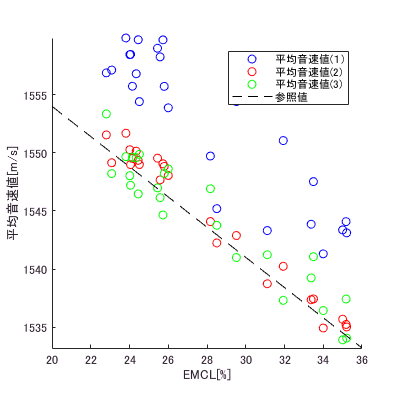

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_12_analyzeRealisticModel')
load('2018_08_12_aveSOS&steSOS_1-25')
load('rate_EMCLs')
[~, num_pattern] = size(aveSOS);
v_muscle = 1580;
v_fat = 1450;
x1 = 20:36;
figure;
hold on
scatter(rate_EMCLs(1,:), aveSOS(1,:),'b');
scatter(rate_EMCLs(1,:), aveSOS2(1,:),'r');
scatter(rate_EMCLs(1,:), aveSOS3(1,:),'g')
plot(x1,v_muscle*(1-x1/100)+v_fat*x1/100,'k--');
% cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_08_08_no_object')
% load('2018_08_08_aveSOS&steSOS')
% scatter(0,aveSOS,'r+');
xlabel('EMCL[%]');
ylabel('平均音速値[m/s]')
legend('平均音速値(１)','平均音速値(2)','平均音速値(3)','参照値')
axis square
axis tight
hold off
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_13_analyzeRealisticModel\EMCL-aveSOS','png',[400,400]);

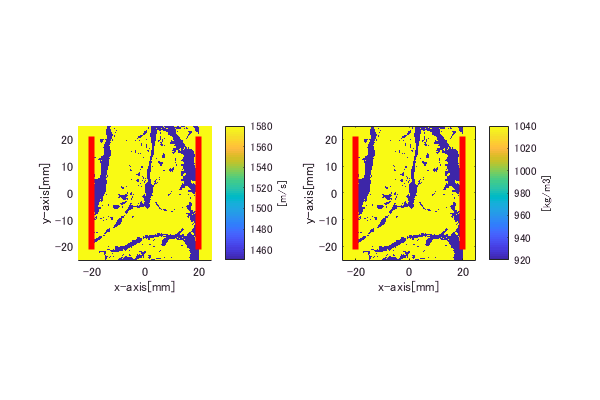

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\medium\2018_08_10_realisticScatter')
t_size = 40.e-3;
t_num = 200;%トランスデューサ数
t_pos = zeros(2, t_num);%センサ位置
t_pos(1,1:t_num/2) = -t_size/2:t_size/(t_num/2-1):t_size/2 ;%素子水平方向距離[m]
t_pos(2,1:t_num/2) = t_size/2;
t_pos(1,t_num/2+1:t_num) = t_pos(1,1:t_num/2);
t_pos(2,t_num/2+1:t_num) = -t_size/2;
figure;
myfilename = sprintf('case1');
load(myfilename)
subplot(1,2,1);
hold on;
imagesc(kgrid.x_vec*1000,kgrid.y_vec*1000,medium.sound_speed);
axis equal
axis tight
scatter(t_pos(2,:)*1000,t_pos(1,:)*1000,'rs','filled');
% [~,ind] = min(tof_cell(101:end,:,i));
% ind = ind+100;
% for j = 1:length(ind)
%     plot([t_pos(2,j)*1000;t_pos(2,ind(j))*1000],[t_pos(1,j)*1000;t_pos(1,ind(j))*1000],'.-k','LineWidth',0.01);
% end
xlabel('x-axis[mm]')
ylabel('y-axis[mm]')
colorbar;
caxis([1450 1580]);
c = colorbar;
c.Label.String = '[m/s]';
subplot(1,2,2);
imagesc(kgrid.x_vec*1000,kgrid.y_vec*1000,medium.density);
axis equal
axis tight
hold on
scatter(t_pos(2,:)*1000,t_pos(1,:)*1000,'rs','filled');
% [~,ind] = min(tof_cell(101:end,:,i));
% ind = ind+100;
% for j = 1:length(ind)
%     plot([t_pos(2,j)*1000;t_pos(2,ind(j))*1000],[t_pos(1,j)*1000;t_pos(1,ind(j))*1000],'.-k','LineWidth',0.01);
% end
xlabel('x-axis[mm]')
ylabel('y-axis[mm]')
colorbar;
% caxis([1450 1580]);
c = colorbar;
set(gca,'YDir','normal');
c.Label.String = '[kg/m3]';
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_13_analyzeRealisticModel\SOS-dens-map-case1','png',[600,400]);

１２：分散をみて速すぎる経路があったら加算しない方法を試す．

%まずはtofデータ一個を取り出して考える．
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_12_analyzeRealisticModel')
% [tof_x, tof_y] = size(tof_data);
%leng変数を使う．
aveSOS4 = zeros(1,25);
leng = zeros(200,100);
t_size = 40.e-3;
t_num = 200;%トランスデューサ数
t_pos = zeros(2, t_num);%センサ位置
t_pos(1,1:t_num/2) = -t_size/2:t_size/(t_num/2-1):t_size/2 ;%素子水平方向距離[m]
t_pos(2,1:t_num/2) = t_size/2;
t_pos(1,t_num/2+1:t_num) = t_pos(1,1:t_num/2);
t_pos(2,t_num/2+1:t_num) = -t_size/2;
v_2_0 = zeros(1,100);
for i = 1:t_num
    for j = 1:t_num/2
        leng(i,j) = sqrt((t_pos(1,i)-t_pos(1,j))^2+(t_pos(2,i)-t_pos(2,j))^2);
    end
end
for ii = 1:25
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_12_analyzeRealisticModel')
    myfilename = sprintf('case%d',ii);
    load(myfilename);
    v_1 = leng./tof_data;
    %これでtofと素子間距離が対応付けられた．プロットする．
    % figure;
    % hold on
    % for ii = 1:t_num/2
    %     scatter(1:t_num/2,v_1(ii+100,1:t_num/2),'k+');
    %     scatter(ii,sum(v_1(t_num/2+1:t_num,ii))/(t_num/2),'ro','filled')
    % end
    v_2 = v_1(101:200,:);
    for  jj = 1:100
        v_2_0(1,jj) = v_2(jj,jj);
    end
    ave_v_2_0 = mean(v_2_0);
    std_v_2_0 = std(v_2_0);
    num_0 = numel(find((v_2_0 > ave_v_2_0 + 2*std_v_2_0)));
    v_2_0((v_2_0 > ave_v_2_0 + 2*std_v_2_0)) = 0;
    aveSOS4(1,ii) = sum(v_2_0)/(numel(v_2_0)-num_0);
    % v_2 = reshape(v_2,[1,10000]);
    % figure;
    % plot(v_2);
    %     for jj = 1:100
    %         v_2_tmp = v_2(:,jj);
    %         ave_v_2 = mean(v_2_tmp);
    %         std_v_2 = std(v_2_tmp);
    %         num_0 = numel(find((v_2_tmp > ave_v_2 + 0.5*std_v_2) | (v_2_tmp < ave_v_2 - 0.5*std_v_2)));
    %         v_2_tmp((v_2_tmp > ave_v_2 + 0.5*std_v_2) | (v_2_tmp < ave_v_2 - 0.5*std_v_2)) = 0;
    %         % A = find(v_2 > ave_v_2 + 2*std_v_2);
    %         % figure;
    %         % plot(av_2);
    %         aveSOS4(1,ii) = aveSOS4(1,ii)+sum(v_2_tmp)/(numel(v_2_tmp)-num_0)/100;
    %     end
end
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_12_analyzeRealisticModel');
myfilename = sprintf('2018_08_12_aveSOS&steSOS_1-25');
save(myfilename,'aveSOS','steSOS','aveSOS2','steSOS2','aveSOS3','aveSOS4','tof_cell');

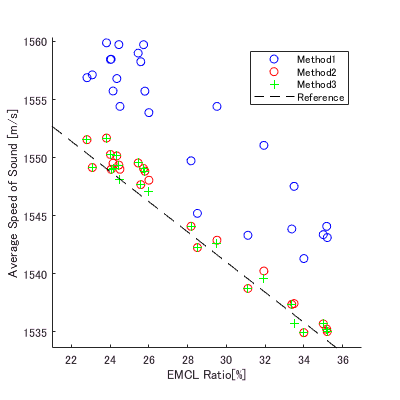

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_12_analyzeRealisticModel')
load('2018_08_12_aveSOS&steSOS_1-25')
load('rate_EMCLs')
[~, num_pattern] = size(aveSOS);
v_muscle = 1580;
v_fat = 1450;
x1 = 20:36;
figure;
hold on
scatter(rate_EMCLs(1,:), aveSOS(1,:),'b');
scatter(rate_EMCLs(1,:), aveSOS2(1,:),'r');
% scatter(rate_EMCLs(1,:), aveSOS3(1,:),'k')
scatter(rate_EMCLs(1,:), aveSOS4(1,:),'g+')
plot(x1,v_muscle*(1-x1/100)+v_fat*x1/100,'k--');
% cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_08_08_no_object')
% load('2018_08_08_aveSOS&steSOS')
% scatter(0,aveSOS,'r+');
xlabel('EMCL Ratio[%]');
ylabel('Average Speed of Sound [m/s]')
legend('Method1','Method2','Method3','Reference')
axis square
axis tight
hold off
xlim([21.0 37.0])
ylim([1533.6 1560.3])
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_13_analyzeRealisticModel\EMCL-aveSOS_2','png',[400,400]);

USE2018に載せる図を作成する．l/tプロットと直線経路図を作成する．

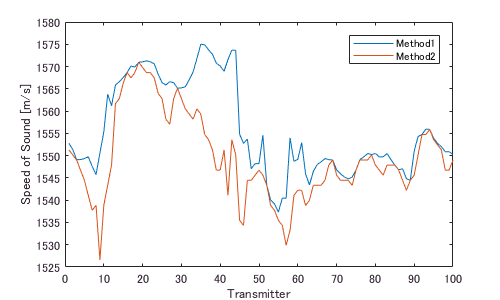

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_12_analyzeRealisticModel')
load('2018_08_12_aveSOS&steSOS_1-25')
t_size = 40.e-3;
t_num = 200;%トランスデューサ数
t_pos = zeros(2, t_num);%センサ位置
t_pos(1,1:t_num/2) = -t_size/2:t_size/(t_num/2-1):t_size/2 ;%素子水平方向距離[m]
t_pos(2,1:t_num/2) = t_size/2;
t_pos(1,t_num/2+1:t_num) = t_pos(1,1:t_num/2);
t_pos(2,t_num/2+1:t_num) = -t_size/2;
[Min,ind]= min(tof_cell(101:end,:,1));
ind = ind+100;
leng = zeros(1,t_num/2);
leng2 = 40e-03;
for k = 1: t_num/2
    leng(1,k) = norm(t_pos(:,k)-t_pos(:,ind(1,k)));
end
v_1 = leng./Min;
v_2 = zeros(1,100);
for jj = 1:t_num/2
    v_2(1,jj) = leng2 / tof_cell(100+jj,jj,1);
end
figure;
plot(1:100,v_1);
xlabel('Transmitter');
ylabel('Speed of Sound [m/s]')
ylim([1525 1580])
hold on
plot(1:100,v_2);
% xlabel('Transmitter');
% ylabel('Speed of Sound [m/s]')
ylim([1525 1580])
hold off
legend('Method1','Method2')
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_13_analyzeRealisticModel\v_plot_method1_and_2','png',[500,300]);

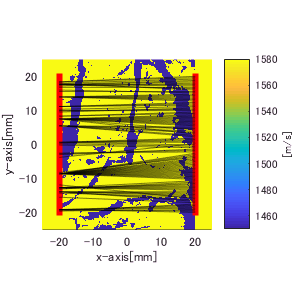

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\medium\2018_08_10_realisticScatter')
t_size = 40.e-3;
t_num = 200;%トランスデューサ数
t_pos = zeros(2, t_num);%センサ位置
t_pos(1,1:t_num/2) = -t_size/2:t_size/(t_num/2-1):t_size/2 ;%素子水平方向距離[m]
t_pos(2,1:t_num/2) = t_size/2;
t_pos(1,t_num/2+1:t_num) = t_pos(1,1:t_num/2);
t_pos(2,t_num/2+1:t_num) = -t_size/2;
figure;
myfilename = sprintf('case1');
load(myfilename)
hold on;
imagesc(kgrid.x_vec*1000,kgrid.y_vec*1000,medium.sound_speed);
axis equal
axis tight
scatter(t_pos(2,:)*1000,t_pos(1,:)*1000,'rs','filled');
[~,ind] = min(tof_cell(101:end,:,1));
ind = ind+100;
% for j = 1:length(ind)
%     plot([t_pos(2,j)*1000;t_pos(2,j+100)*1000],[t_pos(1,j)*1000;t_pos(1,j+100)*1000],'.-g','LineWidth',0.01);
% end
for j = 1:length(ind)
    patch([t_pos(2,j)*1000;t_pos(2,ind(j))*1000],[t_pos(1,j)*1000;t_pos(1,ind(j))*1000],'.-k','LineWidth',0.01,'FaceAlpha',.3,'EdgeAlpha',.3);
end

xlabel('x-axis[mm]')
ylabel('y-axis[mm]')
% title(myfilename);
colorbar;
caxis([1450 1580]);
c = colorbar;
c.Label.String = '[m/s]';
hold off;

exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_13_analyzeRealisticModel\fastest_path_plot','png',[300,300]);

相関係数を求めるｌ．method1 method2について

aveSOS_mat = zeros(2,25);
aveSOS_mat(1,:) = rate_EMCLs(1,:);
aveSOS_mat(2,:) = aveSOS(1,:);
aveSOS2_mat = zeros(2,25);
aveSOS2_mat(1,:) = rate_EMCLs(1,:);
aveSOS2_mat(2,:) = aveSOS2(1,:);
r1 = corr2(aveSOS,rate_EMCLs)

r1 = -0.8998

r2 = corr2(aveSOS2,rate_EMCLs)

r2 = -0.9862

最速パスでの平均音速値の平均と分散，EMCL含有率との共分散を出す．

ave_aveSOS = mean(aveSOS)

ave_aveSOS = 1.5524e+03

w = 1;
sx2 = std(aveSOS,w,2)^2

sx2 = 40.3802

sxz = cov(aveSOS,rate_EMCLs,w);
sxz = sxz(1,2)

sxz = -24.3880

MSEを求める．

v_muscle = 1580;
v_fat = 1450;
ref = zeros(2,25);
ref(1,:) = rate_EMCLs(1,:);
ref(2,:) = v_muscle*(1-ref(1,:)/100)+v_fat*ref(1,:)/100;
err = immse(ref,aveSOS_mat)

err = 42.5866

err2 = immse(ref,aveSOS2_mat)

err2 = 1.0380

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_08_12_realisticScatter')
cd('case1')
load('rfdata.mat')
load('kgrid.mat')

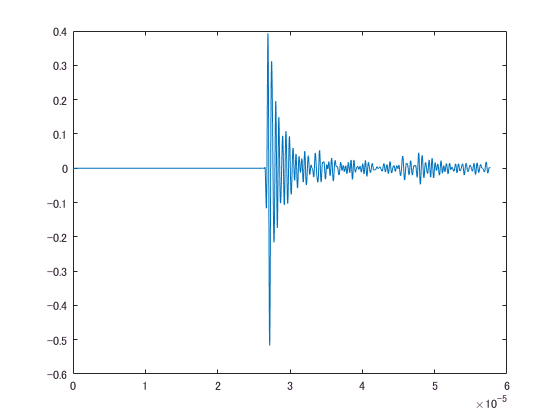

figure;
plot(kgrid.t_array(1,:),rfdata(:,181,80));